image1 = imread("./SR/images/train_images/5.png");
image2 = imread("./SR/images/train_images/2.png");
image3 = imread("./SR/images/train_images/4.png");

starrydl = load("./NST/starryNight.mat");
vanGoghdl = load("./NST/vanGogh.mat");
wavedl = load("./NST/wave.mat");

starryNight = imread("./assets/styles/starryNight.jpg");
vanGogh = imread("./assets/styles/vanGogh.jpg");
wave = imread("./assets/styles/wave.jpg");

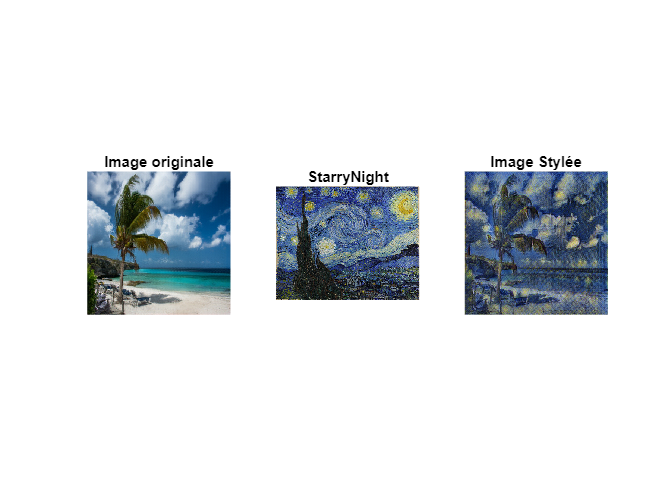

% Starry Night Stylisation
dlX = dlarray(single(image1),'SSCB');
dlY = predict(starrydl.dlnetTransform,dlX);
Y = 255*(tanh(dlY)+1)/2;
styledImage= uint8(gather(extractdata(Y)));

figure
subplot(1,3,1);
imshow(image1);
title("Image originale");
subplot(1,3,2);
imshow(starryNight);
title("StarryNight");
subplot(1,3,3);
imshow(styledImage);
title("Image Stylée");

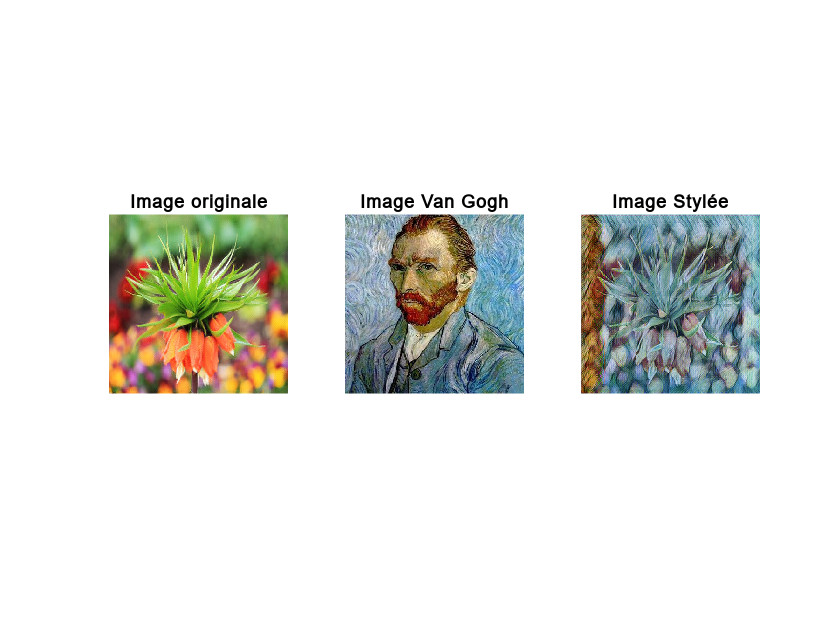

% Van Gogh Stylisation
dlX = dlarray(single(image2),'SSCB');
dlY = predict(vanGoghdl.dlnetTransform,dlX);
Y = 255*(tanh(dlY)+1)/2;
styledImage= uint8(gather(extractdata(Y)));
figure
subplot(1,3,1);
imshow(image2);
title("Image originale");
subplot(1,3,2);
imshow(vanGogh);
title("Image Van Gogh");
subplot(1,3,3);
imshow(styledImage);
title("Image Stylée");

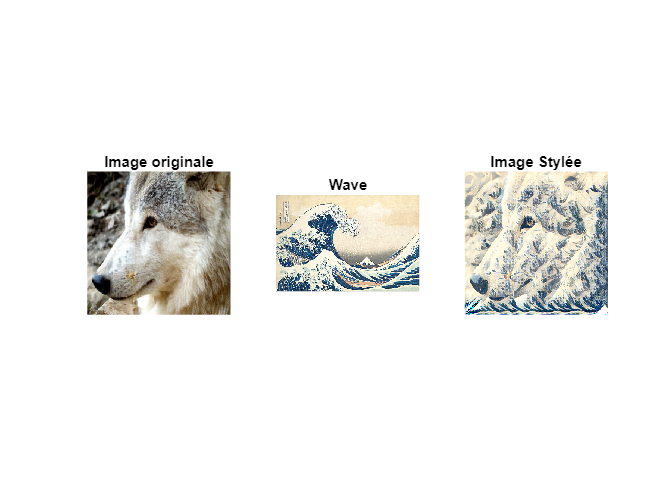

% Wave Stylisation
dlX = dlarray(single(image3),'SSCB');
dlY = predict(wavedl.dlnetTransform,dlX);
Y = 255*(tanh(dlY)+1)/2;
styledImage= uint8(gather(extractdata(Y)));
figure
subplot(1,3,1);
imshow(image3);
title("Image originale");
subplot(1,3,2);
imshow(wave);
title("Wave")
subplot(1,3,3);
imshow(styledImage);
title("Image Stylée");